tic()
imds = imageDatastore('/media/titan/Storage 1/256_ObjectCategories', 'IncludeSubfolders', true, ...
    'LabelSource', 'foldernames');

tbl = countEachLabel(imds)

tbl = 257×2 table
    Label    Count
    _____    _____

     001       98 
     002       97 
     003      151 
     004      127 
     005      148 
     006       90 
     007      106 
     008      232 
     009      102 
     010       94 
     011      278 
     012      216 
     013       98 
     014       86 
     015      122 
     016       91 


minSetCount = min(tbl{:,2}); % determine the smallest amount of images in a category

% SETUP

% number of images from each class to be placed in the dataset
% use minSetCount to use the largest possible number
numImgs = .9999

numImgs = 0.9999

% ratio of training data to test data
trainRatio = .6

trainRatio = 0.6000

% mini batch size: uses more memory when higher but can speed up stuff 
% 32 usually reasonable, decrease if running out of memory
miniSize = 32

miniSize = 32


% Use splitEachLabel method to trim the set. Middle argument = num of images
imds1 = splitEachLabel(imds, numImgs, 'randomize');

% Notice that each set now has exactly the same number of images.
countEachLabel(imds1)

ans = 257×2 table
    Label    Count
    _____    _____

     001       98 
     002       97 
     003      151 
     004      127 
     005      148 
     006       90 
     007      106 
     008      232 
     009      102 
     010       94 
     011      278 
     012      216 
     013       98 
     014       86 
     015      122 
     016       91 



[imdsTrain,imdsTest] = splitEachLabel(imds,0.7,'randomized');

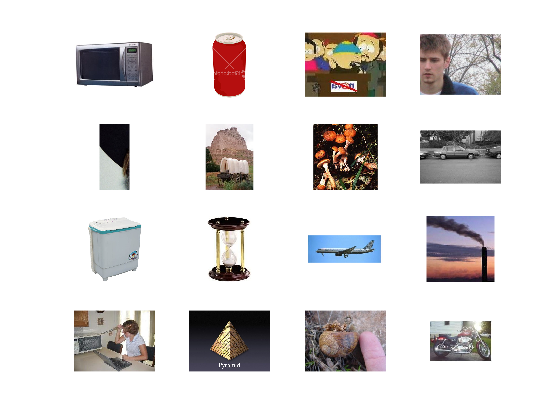

% show some sample images
numTrainImages = numel(imdsTrain.Labels);
idx = randperm(numTrainImages,16);
figure
for i = 1:16
    subplot(4,4,i)
    I = readimage(imdsTrain,idx(i));
    imshow(I)
end

% Load pre-trained AlexNet
net1 = alexnet()

net1 =   SeriesNetwork with properties:

    Layers: [25×1 nnet.cnn.layer.Layer]



% View the CNN architecture
net1.Layers

ans =   25x1 Layer array with layers:

     1   'data'     Image Input                   227x227x3 images with 'zerocenter' normalization
     2   'conv1'    Convolution                   96 11x11x3 convolutions with stride [4  4] and padding [0  0  0  0]
     3   'relu1'    ReLU                          ReLU
     4   'norm1'    Cross Channel Normalization   cross channel normalization with 5 channels per element
     5   'pool1'    Max Pooling                   3x3 max pooling with stride [2  2] and padding [0  0  0  0]
     6   'conv2'    Convolution                   256 5x5x48 convolutions with stride [1  1] and padding [2  2  2  2]
     7   'relu2'    ReLU                          ReLU
     8   'norm2'    Cross Channel Normalization   cross channel normalization with 5 channels per element
     9   'pool2'    Max Pooling                   3x3 max pooling with stride [2  2] and padding [0  0  0  0]
    10 

% Load pre-trained VGG19
net2 = vgg19()

net2 =   SeriesNetwork with properties:

    Layers: [47×1 nnet.cnn.layer.Layer]



net2.Layers

ans =   47x1 Layer array with layers:

     1   'input'     Image Input             224x224x3 images with 'zerocenter' normalization
     2   'conv1_1'   Convolution             64 3x3x3 convolutions with stride [1  1] and padding [1  1  1  1]
     3   'relu1_1'   ReLU                    ReLU
     4   'conv1_2'   Convolution             64 3x3x64 convolutions with stride [1  1] and padding [1  1  1  1]
     5   'relu1_2'   ReLU                    ReLU
     6   'pool1'     Max Pooling             2x2 max pooling with stride [2  2] and padding [0  0  0  0]
     7   'conv2_1'   Convolution             128 3x3x64 convolutions with stride [1  1] and padding [1  1  1  1]
     8   'relu2_1'   ReLU                    ReLU
     9   'conv2_2'   Convolution             128 3x3x128 convolutions with stride [1  1] and padding [1  1  1  1]
    10   'relu2_2'   ReLU                    ReLU
    11   'pool2'     Max Pooling   

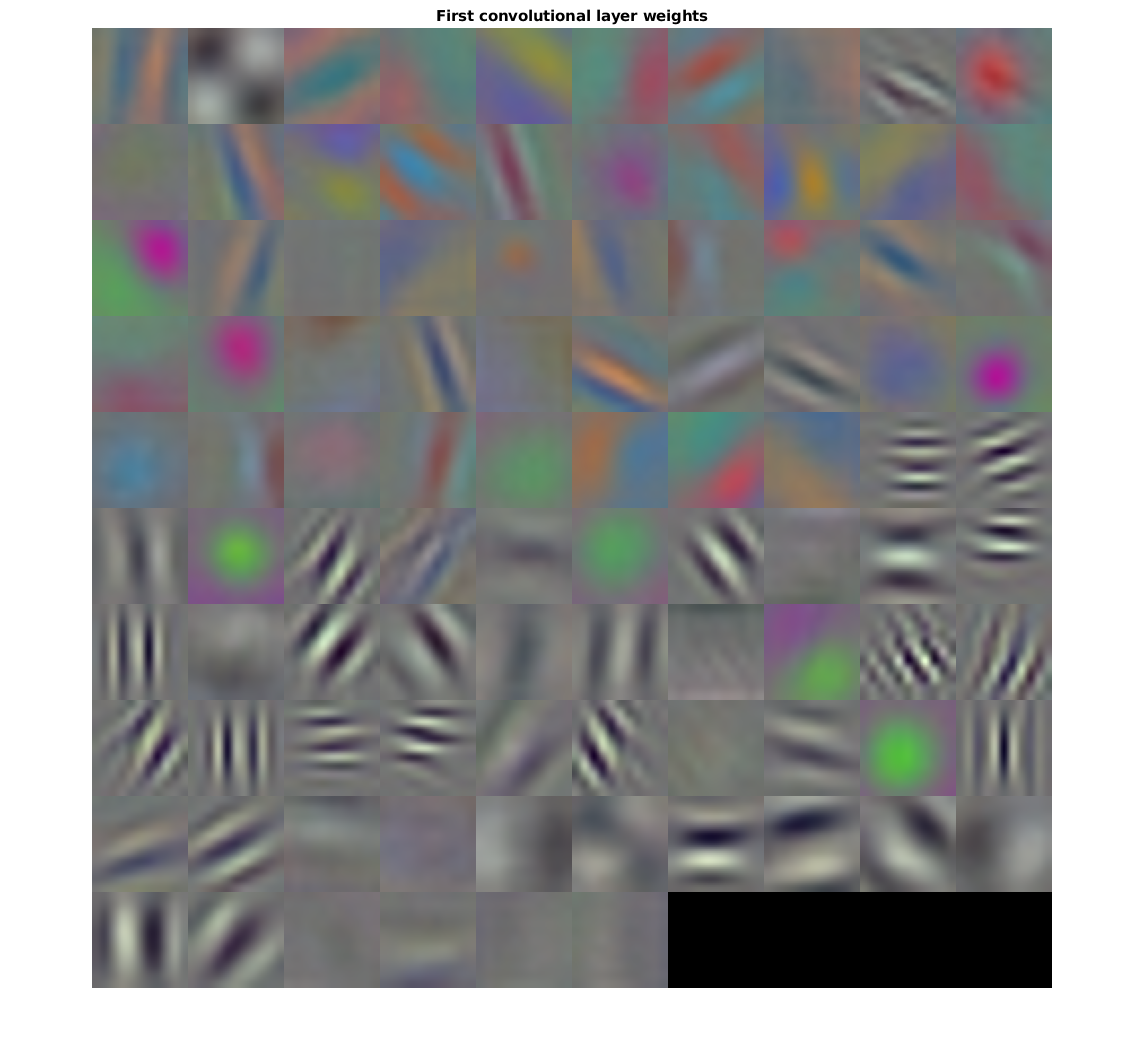

% Get the network weights for the second convolutional layer
w1 = net1.Layers(2).Weights;

% Scale and resize the weights for visualization
w1 = mat2gray(w1);
w1 = imresize(w1,5);

% Display a montage of network weights. There are 96 individual sets of
% weights in the first layer.
figure
montage(w1)
title('First convolutional layer weights')

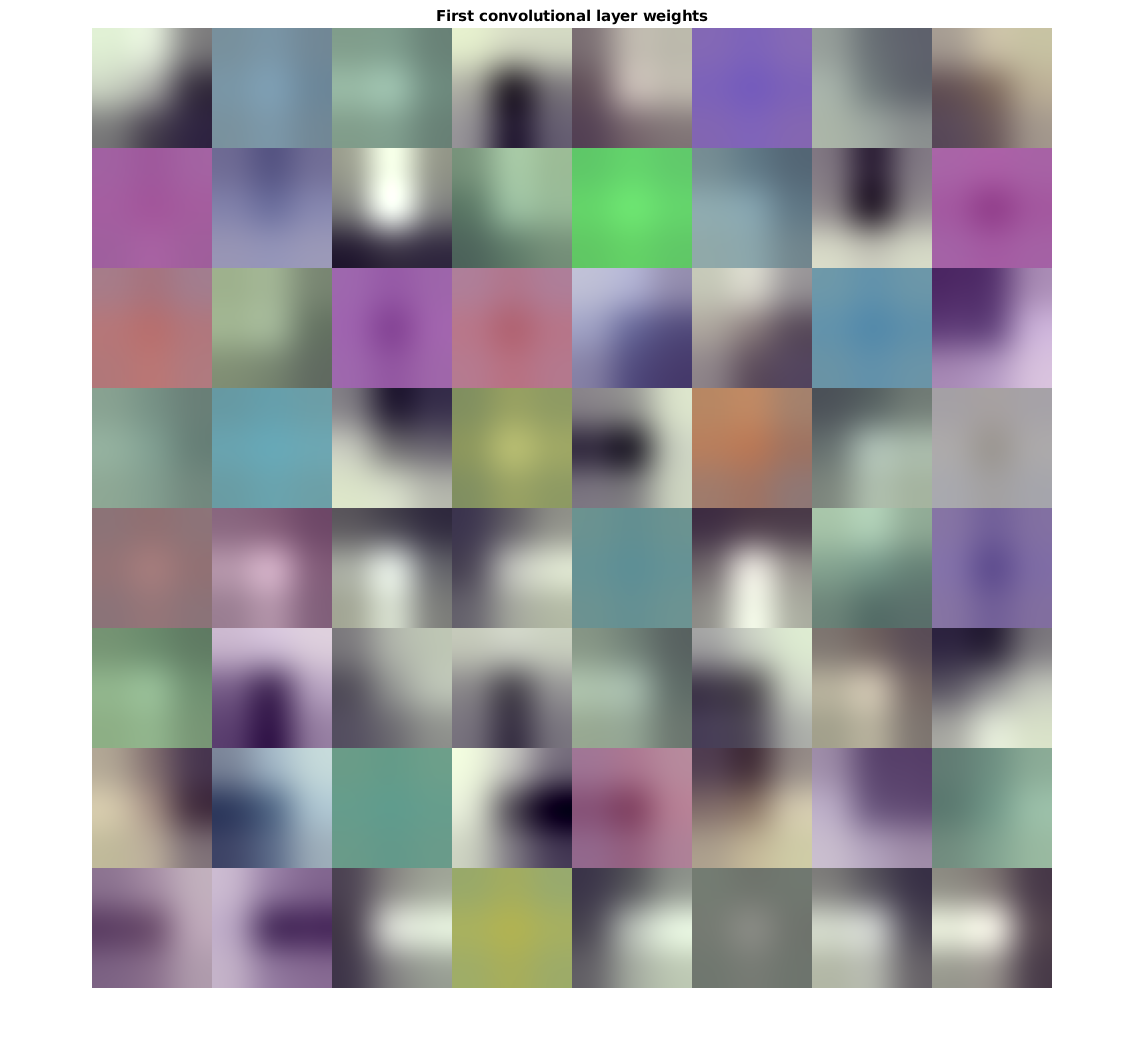

% Get the network weights for the second convolutional layer
w2 = net2.Layers(2).Weights;

% Scale and resize the weights for visualization
w2 = mat2gray(w2);
w2 = imresize(w2,5);

% Display a montage of network weights. There are 96 individual sets of
% weights in the first layer.
figure
montage(w2)
title('First convolutional layer weights')

augimdsTrain = augmentedImageDatastore(inputSize(1:2),imdsTrain);

Undefined function or variable 'inputSize'.

augimdsTest = augmentedImageDatastore(inputSize(1:2),imdsTest);

layer = 'fc7';
featuresTrain = activations(net,augimdsTrain,layer,'OutputAs','rows',...
    'ExecutionEnvironment','gpu')
featuresTest = activations(net,augimdsTest,layer,'OutputAs','rows',...
    'ExecutionEnvironment','gpu')

YTrain = imdsTrain.Labels;
YTest = imdsTest.Labels;

classifier = fitcecoc(featuresTrain,YTrain);

YPred = predict(classifier,featuresTest);

% Display four sample test images with their predicted labels.

idx = [1 5 10 15];
figure
for i = 1:numel(idx)
    subplot(2,2,i)
    I = readimage(imdsTest,idx(i));
    label = YPred(idx(i));
    imshow(I)
    title(char(label))
end

%fusionFeatures = trainingFeatures1 + trainingFeatures2;
%fusionFeatures

% Tabulate the results using a confusion matrix.
confMat = confusionmat(YTest, YPred);

% Convert confusion matrix into percentage form
confMat = bsxfun(@rdivide,confMat,sum(confMat,2))

% Display the mean accuracy
mean(diag(confMat))

newImage = fullfile('101_ObjectCategories', 'airplanes', 'image_0690.jpg');

% Pre-process the images as required for the CNN
img = readAndPreprocessImage1(newImage);

% Extract image features using the CNN
imageFeatures = activations(net1, img, featureLayer);

% Make a prediction using the classifier
label = predict(classifier, imageFeatures)
toc()

function Iout = readAndPreprocessImage1(filename)

        I = imread(filename);

        % Some images may be grayscale. Replicate the image 3 times to
        % create an RGB image.
        if ismatrix(I)
            I = cat(3,I,I,I);
        end

        % Resize the image as required for Alexnet.
        Iout = imresize(I, [227 227]);

        % Note that the aspect ratio is not preserved. In Caltech 101, the
        % object of interest is centered in the image and occupies a
        % majority of the image scene. Therefore, preserving the aspect
        % ratio is not critical. However, for other data sets, it may prove
        % beneficial to preserve the aspect ratio of the original image
        % when resizing.
end

function Iout = readAndPreprocessImage2(filename)

        I = imread(filename);

        % Some images may be grayscale. Replicate the image 3 times to
        % create an RGB image.
        if ismatrix(I)
            I = cat(3,I,I,I);
        end

        % Resize the image as required for VGG19.
        Iout = imresize(I, [224 224]);

        % Note that the aspect ratio is not preserved. In Caltech 101, the
        % object of interest is centered in the image and occupies a
        % majority of the image scene. Therefore, preserving the aspect
        % ratio is not critical. However, for other data sets, it may prove
        % beneficial to preserve the aspect ratio of the original image
        % when resizing.
end